# Setup

## Set Parameters for Chronux 

% Setting parameters
params.Fs = 1000; %Sampling frequency of input data (1000 = 1000 hz = 1 sample per millisecond)
params.fpass = [0 100]; % Which frequencies to look at [lowest_wanted highest_wanted]
params.pad = 0; % will add 0's to fit into a power of 2 for better calculation (0 is default and adds 0's to the next power of 2)
TW = 5; % the time-bandwidth product 
K = 9; % the number of tapers, K = 2*TW - 1 
params.tapers = [TW K]; 
params.err = [2 0.05]


## Set General Parameters

Gparams.window = 20
Gparams.movingwin = [20 1]
Gparams.alpha = 0.9965
Gparams.standardized_len= 0
Gparams.artifact_filter_limit = 0.5

##  Load Each Dataset

I have removed CT7 and KO7 here as the trials were noisy

I have removed CT4 and KO4 as there is strong 52 Hz Noise

% Load each unhabituated trial for each
controls = {CT1, CT2, CT3, CT5, CT6, CT8}
knockouts = {KO1, KO2, KO3, KO5, KO6, KO8}

all_trials = [controls knockouts]

## Vertically Concatenate Datasets

CT_cat = artifact_filter(vertcat_cell_array(controls), 0.5);
KO_cat = artifact_filter(vertcat_cell_array(knockouts), 0.5);


LFP_analysis_i(controls ,params, Gparams, 'Control') 

LFP_analysis_i(knockouts ,params, Gparams, 'Knockout') 


## Running Data

plot_spectrogram(CT1, [20 1], params)

plot_spectrum({CT_cat, KO_cat}, params, 20, 1)

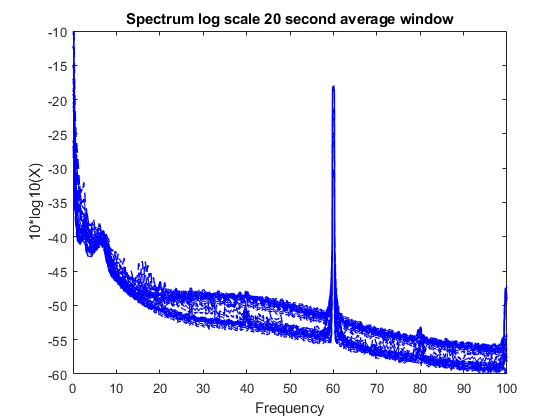

result = 1×12 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = 1×12 cell array
    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}    {1×3 cell}


x = plot_spectrum(all_trials, params, 20, 1)

# Functions

## LFP Total Analysis Individual 

function result = LFP_analysis_i(cell_array,params, Gparams, label) 
for ii = 1:length(cell_array)
    x = cell_array{ii};
    
    % Display Which Dataset is Being Processed
    sprintf ('Processing %s %f', label, ii)
    
    % Plot Raw Data
    title_raw = sprintf('%s %f Raw Data', label, ii)
    figure; plot (x); title(title_raw);
    
    % Remove Artifacts
    x = artifact_filter(x, Gparams.artifact_filter_limit);
    
    % Plot Filtered
    title_filtered = sprintf('%s %f Filtered Data', label, ii)
    figure; plot(x); title(title_filtered)
    
    plot_spectrogram(x, Gparams.movingwin, params);
    
    plot_spectrum_seg(x, Gparams.window, params);
    
    cell_array{ii} = x;    
end
cat = vertcat_cell_array(cell_array);

disp('Plotting All Together')

plot_spectrogram(cat, Gparams.movingwin, params);

plot_spectrum_seg(cat, Gparams.window,params);

plot_spectrum_seg_t_cell(cell_array, Gparams.window, params);

end

## _____________________________________________________________________________

## Calculate and Plot Spectrum Segs 

##     - Optional: Show Error Bars, Plot Together/Individually

function result = plot_spectrum(data, params, window, show_error_01, individual_plot_01, segave_01)

% Set default argument values
if ~exist('window', 'var'), window = 20; end % window is length in seconds to average over
if ~exist('show_error_01', 'var'), show_error_01 = 0 ; end 
if ~exist ('individual_plot_01', 'var'), individual_plot_01 = 0; end
if ~exist('segave_01', 'var'), segave_01 = 1; end % Segave = 1 means it will average over the provided window

% If passing one array this converts it into a cell array for the function to handle
if ~iscell(data)
    data = {data}
end

% Plot and return values given varous conditions (no error bars / error bars; indivudual/ grouped)
if show_error_01 == 1
    
    if individual_plot_01 == 0
        figure;
        for ii = 1:length (data)
            
            [s,f, ~, ~, Serr]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
            hold on 
            
            x{ii} = {s, f, Serr} ;
        end
        
    elseif individual_plot_01 == 1
        for ii = 1:length (data)
            [s,f, ~, ~, Serr]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            figure; plot_vector(s,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
                         
            x{ii} = {s, f, Serr} ;
        end
    end
    
elseif show_error_01 == 0
    if individual_plot_01 == 0
        figure;
        for ii = 1:length (data)
            [s, f] = mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            
            plot_vector(s, f, 'l'); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
            hold on 
            
            x{ii} = {s, f} ;
        end
    elseif individual_plot_01 == 1
        for ii = 1:length (data)
            [s,f]=mtspectrumsegc(data{ii}(:,2),window,params,segave_01);
            
            figure; plot_vector(s,f, 'l'); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
                         
            x{ii} = {s, f} ;
        end
    end
end
    
result = x 

end

## Calculate and Plot Spectrum Segs Together

function result = plot_spectrum_seg_t (arrayx, arrayz, window, params)

% window is length in seconds to average over
segave = 1 ;

% Calculate 
[S1,f1, Serr1]=mtspectrumsegc(arrayx(:,2),window,params,segave);

[S2,f2, Serr2]=mtspectrumsegc(arrayz(:,2),window,params,segave);


% Plot
figure; plot_vector(S1,f1, 'l', Serr1); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
hold on 
plot_vector(S2,f2, 'l', Serr2)

result = {{S1,f1, Serr1}, {S2 f2 Serr2}}
end

## Vertically Concatenate Cell Array

function result = vertcat_cell_array(cell_array)
x = cell_array{1}
for ii = 2: length(cell_array)
    x = vertcat(x,cell_array{ii}) 
end
result = x
end

## Calulate and Plot Spectrum over Average Window

function result = plot_spectrum_seg(arrayx, window, params)

% window is length in seconds to average over
segave = 1 ;
[S,f, ~, ~, Serr]=mtspectrumsegc(arrayx(:,2),window,params,segave);
figure; plot_vector(S,f, 'l', Serr); title('Spectrum log scale 20 second average window'); ylim([-60 -10]); xlabel('Frequency');
result = {S,f, Serr}
end

## Calculate and Plot Spectrogram

function result = plot_spectrogram (arrayx, movingwin, params)

[s, t, f, Serr] = mtspecgramc(arrayx(:,2), movingwin,params);
figure; plot_matrix(s,t,f, 'l', Serr); colorbar; colormap jet; caxis ([-70 -20]); xlabel('Seconds'); ylabel('Frequency');

end

## Filter out Artifacts (Array)

function result = artifact_filter(array, limit)

array(abs(array(:,2)) >= limit, :) = [];

result = array
end

## Standardize Length of Arrays

function result = standardize_length(cell_array, len)
% This function takes a cell array (cell_array) containing a set of arrays
% and makes them all the same length (len) from 1 to len
for ii = 1:length(cell_array)
    cell_array{ii} = cell_array{ii}(1:len,:)
end
result = cell_array
end


## Remove Frequency Band Noise from Cell Array of Datasets

function result = filter_noise(xarray, noiseHz, Fs, alpha)
% This function removes noise from signal with variable alpha and Hz

% Set parameters for filter

omega = 2*pi*noiseHz/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end

## Remove 60Hz Noise from Cell Array of Datasets

function result = remove60(cell_array, Fs)
% This function removes 60 Hz noise from signal

% Set parameters for filter

%%%%global params.Fs

alpha = 0.998; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

for ii = 1:length(cell_array)
    cell_array{ii}(:,2) = (filter(num,den,cell_array{ii}(:,2)))
end
result = cell_array
end

## Remove 60Hz Noise from Array

function result = remove60_nocell(xarray, Fs, alpha)
% This function removes 60 Hz noise from signal

% Set parameters for filter

% alpha = 0.9975; 
omega = 2*pi*60/Fs; 
num = [1 -2*cos(omega) 1];
den = [1 -2*alpha*cos(omega) alpha*alpha];

xarray (:,2) = filter(num,den,xarray(:,2))

result = xarray
end  


## ____________________________________________________________________________

## Percent Running Time

function result = percent_running(running_data)
result = sum(running_data(:) == 1)/length(running_data)
end

## Total Time Running (Seconds)

function result = time_running(running_data)
result = sum(running_data(:) == 1)
fprinf ('Total Time Running is %s \n', result)
end

## Process Running Data into Boolean per Second

function result = process_running_data(running_data)

opto = round(running_data(:,1))
times = 1:length(opto)

win = 1000; %window in ms to look at opto
winstart = [1:win:length(times)-win]; %index corresponding to the start of each window

locomotion = []; %vector of 0 (not moving) and 1 (moving) for each window (1 sec)
for i = 1:length(winstart)
   m = winstart(i);
   optowin = opto(m:m+(win-1));
   optowinDif = diff(optowin); %will be all 0 if every value in optowin is the same
   if isempty(find(optowinDif,1)) %if optowinDif are all 0's
       locomotion(i) = 0; %0 means not moving
   else
       locomotion(i) = 1; %1 = moving
   end
end
result = locomotion
end
